# AAE 567 HW3 Problem6

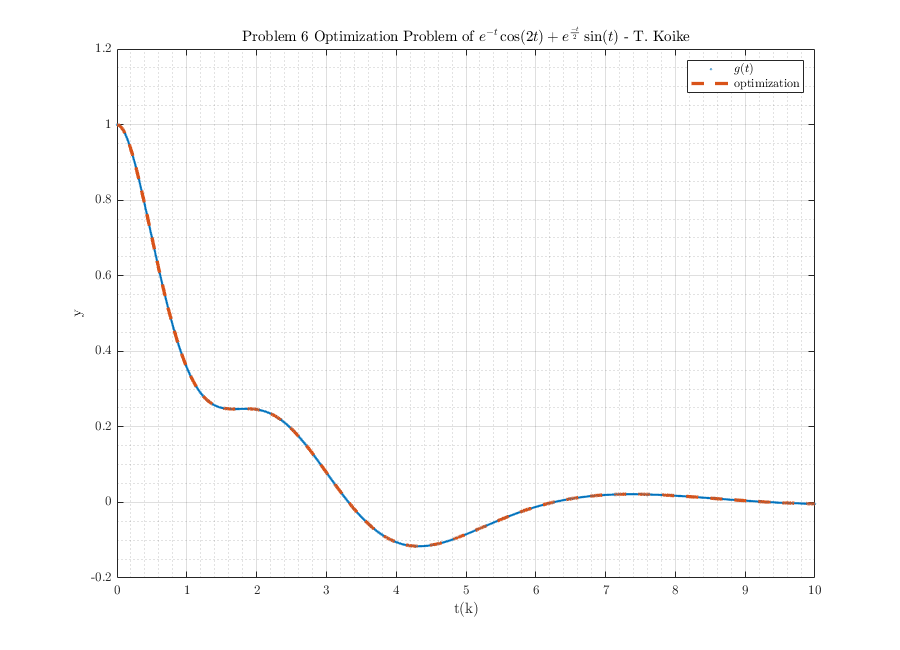

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define the system 
[A,B,C,D] = rmodel(40);

% Define given function
t = linspace(0, 10, 12000)';
y = exp(-t).*cos(2*t) + exp(-t/2).*sin(t);

% Define T
T = zeros(length(y), length(C));
for i = 1:length(T)
    T(i,:) = C * expm(A * t(i));
end

% Compute xhat and the error
xhat = pinv(T)*y;                 % xhat
error = norm(y - T*xhat);         % error

% Plotting
fig = figure("Renderer","painters", "Position",[60 60 900 650]);
    plot(t, y, '.', "MarkerSize", 3)
    hold on; grid on; box on; grid minor;
    plot(t, T * xhat, '--', 'LineWidth',2.5)
    title("Problem 6 Optimization Problem of $e^{-t}\cos(2t) + e^{\frac{-t}{2}}\sin(t)$ - T. Koike")
    xlabel('t(k)')
    ylabel('y')
    legend('$g(t)$', 'optimization')
saveas(fig,"hw3_p6_eqnOpt.png")